%% Ryan Mittelstadt
%% Bi-elliptic Transfer Delta-v Optimization
clc; clear;

% ------------------ Constants ------------------
mu = 3.986004355e5;         % Earth gravitational parameter [km^3/s^2]
r1 = 6378 + 500;            % r1 radius [km]
r2 = 6378 + 1000;           % r2 radius [km]
max_transfer_days = 5;      % Maximum transfer time constraint [days]

% ------------------ Variables ------------------
syms R22 real  % Bi-elliptic intermediate orbit radius

% ------------------ Elipctical Transfer Orbits ------------------
at1 = (r1 + R22)/2;     % Semi-major axis of first transfer ellipse
at2 = (r2 + R22)/2;     % Semi-major axis of second transfer ellipse
atH = (r1 + r2)/2;      % Semi-major axis for singular Hohmann transfer

% ------------------ Velocity components ------------------
% Precompute circular velocities
vc1 = sqrt(mu/r1);      % LEO circular velocity
vc2 = sqrt(mu/r2);      % GEO circular velocity

% Bi-elliptic Transfer
v1 = vc1;                         % LEO Circular Orbit
v2 = sqrt(mu*(2/r1 - 1/at1));     % LEO → R22 Transfer Orbit @ LEO
v3 = sqrt(mu*(2/R22 - 1/at1));    % LEO → R22 Transfer Orbit @ R22
v4 = sqrt(mu*(2/R22 - 1/at2));    % R22 → GEO Transfer Orbit @ R22
v5 = sqrt(mu*(2/r2 - 1/at2));     % R22 → GEO Transfer Orbit @ GEO
v6 = vc2;                         % GEO Circular Orbit

% Singular Hohmann Transfer
vH1 = vc1;                        % LEO Circular Orbit
vH2 = sqrt(mu*(2/r1 - 1/atH));    % LEO → GEO Transfer Orbit @ LEO
vH3 = sqrt(mu*(2/r2 - 1/atH));    % LEO → GEO Transfer Orbit @ GEO
vH4 = vc2;                        % GEO Circular Orbit

% ------------------ Transfer Times ------------------
t = pi*(sqrt(at1^3/mu) + sqrt(at2^3/mu));  % Bi-elliptic transfer time
tH = pi*sqrt(atH^3/mu);                    % Hohmann transfer time

% ------------------ Total Delta Vs ------------------
dV  = abs(v2-v1) + abs(v4-v3) + abs(v6-v5); % Bi-elliptic ΔV
dVH = abs(vH2-vH1) + abs(vH4-vH3);          % Hohmann ΔV

% ------------------ Optimize R22 using fmincon ------------------
dV_fun = matlabFunction(dV,'Vars',R22);  % Convert symbolic ΔV to function
t_fun  = matlabFunction(t,'Vars',R22);   % Convert symbolic transfer time to function
Constraints = @(R22val) deal(t_fun(R22val) - max_transfer_days*86400, []);  % c = t - max days

guess = 1.5*r2;  % Initial guess
lb = r2 + 1;     % Lower bound for R22
ub = 10*r2;      % Upper bound for R22

options = optimoptions('fmincon', ...
    'Display','iter-detailed', ...
    'StepTolerance',1e-12, ... % Tight tolerances so fmincon doesn't ignore small dV gradient
    'OptimalityTolerance',1e-12);
[R22_opt, dV_opt] = fmincon(dV_fun, guess, [], [], [], [], lb, ub, Constraints, options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    1.656885e+00    0.000e+00    2.877e-04
    1       4    1.656885e+00    0.000e+00    2.877e-04    2.874e-04
    2       6    1.656884e+00    0.000e+00    2.877e-04    1.437e-03
    3       8    1.656882e+00    0.000e+00    2.874e-04    7.186e-03
    4      10    1.656872e+00    0.000e+00    2.874e-04    3.593e-02
    5      12    1.656820e+00    0.000e+00    2.874e-04    1.798e-01
    6      14    1.656561e+00    0.000e+00    2.875e-04    8.989e-01
    7      16    1.655268e+00    0.000e+00    2.876e-04    4.495e+00
    8      18    1.648784e+00    0.000e+00    2.885e-04    2.249e+01
    9      20    1.615987e+00    0.000e+00    2.927e-04    1.128e+02
   10      22    1.441891e+00    0.000e+00    3.158e-04    5.721e+02
   11      24    2.702858e-01    0.000e+00    4.960e-04    2.960e+03
   12      26    2.629310e-01    0.000e+00    3


% ------------------ Find R22 using fsolve sweep ------------------

% Symbolic derivative of ΔV w.r.t R22
dVprime_sym = diff(dV, R22);
dVprime_fun = matlabFunction(dVprime_sym, 'Vars', R22);

% Turn off fsolve display b/c looping clutter
options_fs = optimoptions('fsolve','Display','off');

% ------------------ Iterative sweep parameters ------------------
initial_guesses = [r2*1.01, r2*2, r2*5, r2*10];  % wide initial guesses
max_sweeps      = 6;       % number of refinement iterations
delta           = 100;     % initial refinement interval (km)
finer_steps     = 20;      % number of guesses per refinement sweep
tolerance_dV    = 1e-5;    % stop if ΔV improvement is very small

dV_prev = Inf;  % store previous best ΔV

% ------------------ Iterative refinement loop ------------------
for sweep = 1:max_sweeps
    R22_candidates = zeros(size(initial_guesses));  % store fsolve roots
    dV_candidates  = zeros(size(initial_guesses));  % store corresponding ΔV
    
    for i = 1:length(initial_guesses)
        guess = initial_guesses(i);
        [R22_sol, ~] = fsolve(dVprime_fun, guess, options_fs);
        
        % Accept only physically meaningful solutions (R22 > r2)
        if R22_sol > r2
            R22_candidates(i) = R22_sol;
            dV_candidates(i)  = double(subs(dV, R22, R22_sol));
        else
            R22_candidates(i) = NaN;
            dV_candidates(i)  = Inf;
        end
    end
    
    % Pick the candidate with minimum ΔV
    [dV_best, idx_min] = min(dV_candidates);
    R22_best = R22_candidates(idx_min);
    
    fprintf('fsolve Sweep %d: Best R22 = %.3f km, ΔV = %.5f km/s\n', sweep, R22_best, dV_best);
    
    % Stop if ΔV improvement is negligible
    if abs(dV_prev - dV_best) < tolerance_dV
        break;
    end
    dV_prev = dV_best;
    
    % Prepare finer sweep around the best candidate for next iteration
    delta = delta / 2;  % shrink interval gradually
    initial_guesses = linspace(R22_best - delta, R22_best + delta, finer_steps);
end

fsolve Sweep 1: Best R22 = 7451.780 km, ΔV = 0.29888 km/s
fsolve Sweep 2: Best R22 = 7401.780 km, ΔV = 0.27421 km/s
fsolve Sweep 3: Best R22 = 7379.412 km, ΔV = 0.26310 km/s
fsolve Sweep 4: Best R22 = 7378.754 km, ΔV = 0.26277 km/s
fsolve Sweep 5: Best R22 = 7378.425 km, ΔV = 0.26261 km/s
fsolve Sweep 6: Best R22 = 7378.260 km, ΔV = 0.26253 km/s



% ------------------ Display Results ------------------
fprintf('\nFinal fsolve iterative solution: R22 = %.3f km, ΔV = %.5f km/s\n', R22_best, dV_best);


Final fsolve iterative solution: R22 = 7378.260 km, ΔV = 0.26253 km/s



t_sec = double(t_fun(R22_opt));
days = floor(t_sec/86400);
hours = floor(mod(t_sec,86400)/3600);
mins = floor(mod(t_sec,3600)/60);
secs = floor(mod(t_sec,60));

fprintf('Bi-Elliptic Transfer using fmincon:\n');

Bi-Elliptic Transfer using fmincon:


fprintf('   Optimized ΔV = %.3f km/s\n', double(dV_opt));

   Optimized ΔV = 0.263 km/s


fprintf('   Optimal R22 = %.3f km\n', double(R22_opt));

   Optimal R22 = 7379.000 km


fprintf('   Transfer Time = %.3f s\n', t_sec);

   Transfer Time = 6148.664 s


fprintf('                 = %d days, %d hrs, %d mins, %d s\n\n', days,hours,mins,secs);

                 = 0 days, 1 hrs, 42 mins, 28 s




tH_sec = double(tH);
days = floor(tH_sec/86400);
hours = floor(mod(tH_sec,86400)/3600);
mins = floor(mod(tH_sec,3600)/60);
secs = floor(mod(tH_sec,60));

fprintf('Hohmann Transfer:\n');

Hohmann Transfer:


fprintf('   ΔV = %.3f km/s\n', double(dVH));

   ΔV = 0.262 km/s


fprintf('   Transfer Time = %.3f s\n', tH_sec);

   Transfer Time = 2994.557 s


fprintf('                 = %d days, %d hrs, %d mins, %d s\n', days,hours,mins,secs);

                 = 0 days, 0 hrs, 49 mins, 54 s


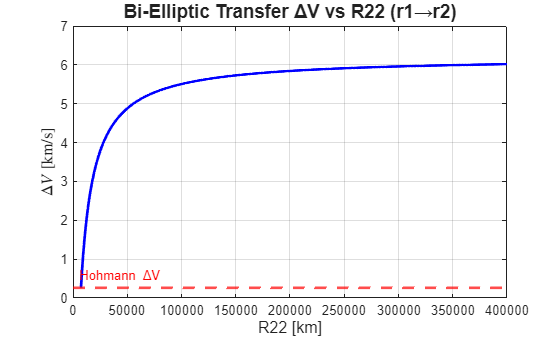


% ================================ r1 → GEO R22 Sweep ================================
% Shows dV and Transfer Time for a Sweep of R22 values for r1→r2 transfer
R22_sweep = linspace(r2+1,4e5,1000);  

at1_s = (r1 + R22)/2;      % Semi-major axis first transfer
at2_s = (r2 + R22)/2;      % Semi-major axis second transfer
v1_s = vc1;                % r1 circular velocity
v2_s = sqrt(mu*(2/r1 - 1/at1_s));
v3_s = sqrt(mu*(2/R22 - 1/at1_s));
v4_s = sqrt(mu*(2/R22 - 1/at2_s));
v5_s = sqrt(mu*(2/r2 - 1/at2_s));
v6_s = vc2;                % r2 circular velocity

dV_s = abs(v2_s-v1_s) + abs(v4_s-v3_s) + abs(v6_s-v5_s); % Bi-elliptic ΔV
t_s  = pi*(sqrt(at1_s^3/mu) + sqrt(at2_s^3/mu));         % Bi-elliptic transfer time

dV_fun_s = matlabFunction(dV_s,'Vars',R22);
t_fun_s  = matlabFunction(t_s,'Vars',R22);

dV_vals_s = dV_fun_s(R22_sweep);
t_vals_s  = t_fun_s(R22_sweep);

% ------------------ Plot ΔV for r1→r2 ------------------
figure;
plot(R22_sweep,dV_vals_s,'b','LineWidth',2)
hold on
yline(double(dVH),'--r','LineWidth',2,'Label','Hohmann \DeltaV','LabelHorizontalAlignment','left');
xlabel('R22 [km]','FontSize',12)
ylabel('$\Delta V$ [km/s]','FontSize',12,'Interpreter','latex')
title('Bi-Elliptic Transfer ΔV vs R22 (r1→r2)','FontSize',14)
grid on
ax = gca; ax.XAxis.Exponent = 0; ax.YAxis.Exponent = 0;

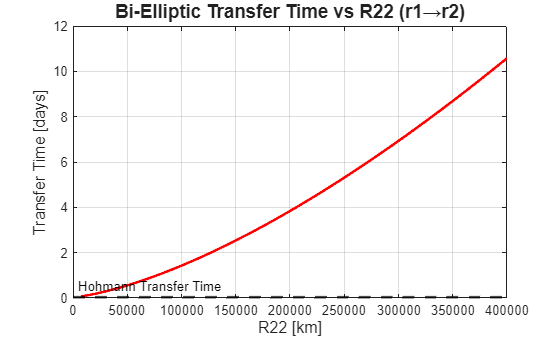


% ------------------ Plot Transfer Time for r1→r2 ------------------
figure;
plot(R22_sweep,t_vals_s./86400,'r','LineWidth',2)
hold on
yline(double(tH)/86400,'--k','LineWidth',2,'Label','Hohmann Transfer Time','LabelHorizontalAlignment','left');
xlabel('R22 [km]','FontSize',12)
ylabel('Transfer Time [days]','FontSize',12)
title('Bi-Elliptic Transfer Time vs R22 (r1→r2)','FontSize',14)
grid on
ax = gca; ax.XAxis.Exponent = 0; ax.YAxis.Exponent = 0;

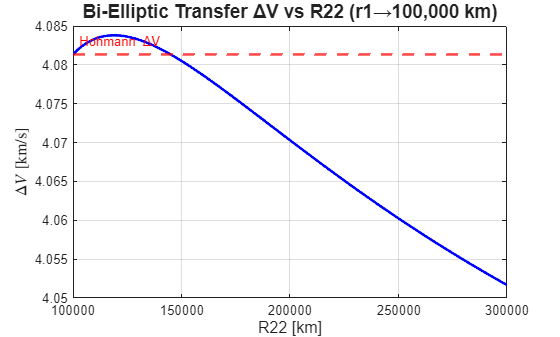


% ================================ r1 → 100,000 km sweep ================================ 
% Shows dV and Transfer Time for a Sweep of R22 values for r1→100km transfer
r_target = 1e5; 
R22_sweep2 = linspace(r_target+1,3e5,1000);    
at1_s2 = (r1 + R22)/2;         % Semi-major axis first transfer
at2_s2 = (r_target + R22)/2;   % Semi-major axis second transfer
v_LEO = vc1;                   % r1 circular velocity
v_target = sqrt(mu/r_target);  % Target orbit circular velocity
v2_s2 = sqrt(mu*(2/r1 - 1/at1_s2));
v3_s2 = sqrt(mu*(2/R22 - 1/at1_s2));
v4_s2 = sqrt(mu*(2/R22 - 1/at2_s2));
v5_s2 = sqrt(mu*(2/r_target - 1/at2_s2));

dV_s2 = abs(v2_s2 - v_LEO) + abs(v4_s2 - v3_s2) + abs(v_target - v5_s2);  % Bi-elliptic ΔV
t_s2  = pi*(sqrt(at1_s2^3/mu) + sqrt(at2_s2^3/mu));                       % Bi-elliptic transfer time

dV_fun_s2 = matlabFunction(dV_s2,'Vars',R22);
t_fun_s2  = matlabFunction(t_s2,'Vars',R22);

dV_vals_s2 = dV_fun_s2(R22_sweep2);
t_vals_s2  = t_fun_s2(R22_sweep2);

% ------------------ Hohmann for r1 → 100,000 km ------------------
a_H_target = (r1 + r_target)/2;        % Semi-major axis of Hohmann transfer
v_trans_LEO = sqrt(mu*(2/r1 - 1/a_H_target));
v_trans_target = sqrt(mu*(2/r_target - 1/a_H_target));
dVH_target = abs(v_trans_LEO - vc1) + abs(v_target - v_trans_target);
tH_target  = pi*sqrt(a_H_target^3/mu);

% ------------------ Plot ΔV for r1 → 100,000 km ------------------
figure;
plot(R22_sweep2,dV_vals_s2,'b','LineWidth',2)
hold on
yline(dVH_target,'--r','LineWidth',2,'Label','Hohmann \DeltaV','LabelHorizontalAlignment','left');
xlabel('R22 [km]','FontSize',12)
ylabel('$\Delta V$ [km/s]','FontSize',12,'Interpreter','latex')
title('Bi-Elliptic Transfer ΔV vs R22 (r1→100,000 km)','FontSize',14)
grid on
ax = gca; ax.XAxis.Exponent = 0; ax.YAxis.Exponent = 0;

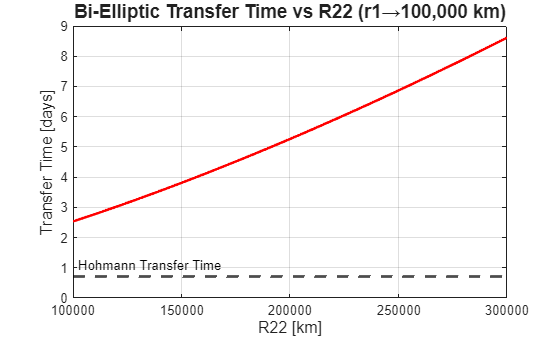


% ------------------ Plot Transfer Time for r1 → 100,000 km ------------------
figure;
plot(R22_sweep2,t_vals_s2./86400,'r','LineWidth',2)
hold on
yline(tH_target/86400,'--k','LineWidth',2,'Label','Hohmann Transfer Time','LabelHorizontalAlignment','left');
xlabel('R22 [km]','FontSize',12)
ylabel('Transfer Time [days]','FontSize',12)
title('Bi-Elliptic Transfer Time vs R22 (r1→100,000 km)','FontSize',14)
grid on
ax = gca; ax.XAxis.Exponent = 0; ax.YAxis.Exponent = 0;